# Delay and Add

Se probó Delay And Add para intentar separar las dos fuentes de los mismos audios que se analizaron con MUSIC. Aquí la voz de las personas hablando tiene similar energia, lo que hace que la separación por este método no sea tan efectiva. 

Intentaré hacer la prueba con audios en los que la interferencia tenga menor energía para ver si el algoritmo está operando correctamente.

addpath("G:\Mi unidad\MCC\extra\MUSIC");

### Obtención de la dirección de las fuentes

[signal1, Fs] = audioread("wav_mic1_2_fuentes.wav");
[signal2, Fs] = audioread("wav_mic2_2_fuentes.wav");
[signal3, Fs] = audioread("wav_mic3_2_fuentes.wav");
tArray = (0:length(signal1)-1)*(1/Fs);
fftCalculator = FFTCalculator();

fftCalculator =   FFTCalculator with no properties.


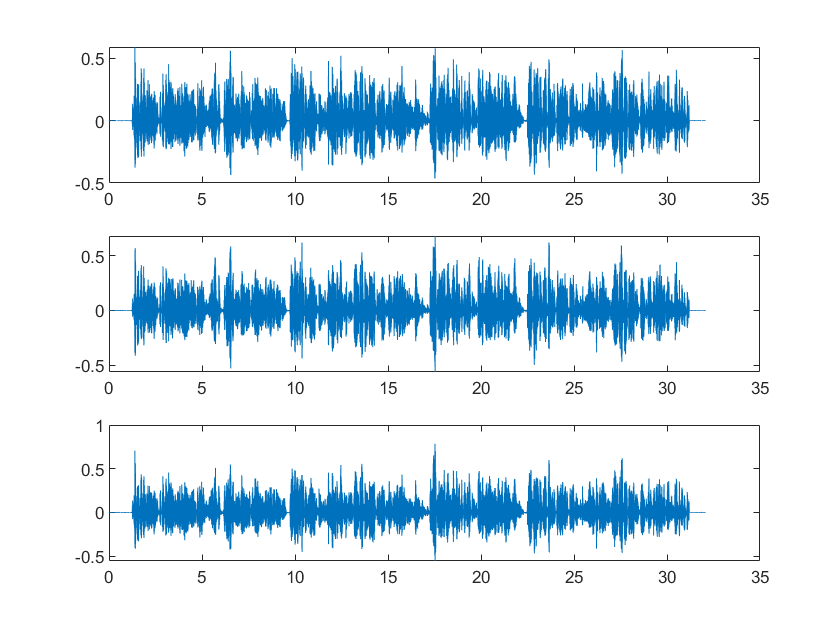


[freqs, spectrum1] = fftCalculator.getFFT(signal1, tArray);
[freqs, spectrum2] = fftCalculator.getFFT(signal2, tArray);
[freqs, spectrum3] = fftCalculator.getFFT(signal3, tArray);


figure()
subplot(3,1,1)
plot(tArray, signal1)
subplot(3,1,2)
plot(tArray, signal2)
subplot(3,1,3)
plot(tArray, signal3)

signals = [spectrum1, spectrum2, spectrum3];
distanceBetweenMics = 0.18;
nSources = 2;
phases = [0,0,60];
minFreq = 600;
maxFreq = 650;
minAngle = -180;
maxAngle = 180;
musicDetector = MUSICDetector(nSources, signals, tArray, distanceBetweenMics, phases);

[dirs, delays] = musicDetector.getSourcesDirections(minFreq, maxFreq, minAngle, maxAngle);

%minFreq = 300;
%maxFreq = 20000;

minFreq = 3;
maxFreq = 30000;
%delays = musicDetector.getTimeDelays([-30,80]);
separator = DelayAndSumSeparator(delays);
%Separamos la primera fuente
signals = [signal1, signal2, signal3];
separatedSignal1 = separator.separateSignal(1, tArray, signals);
audiowrite("separado_1.wav", separatedSignal1, Fs);

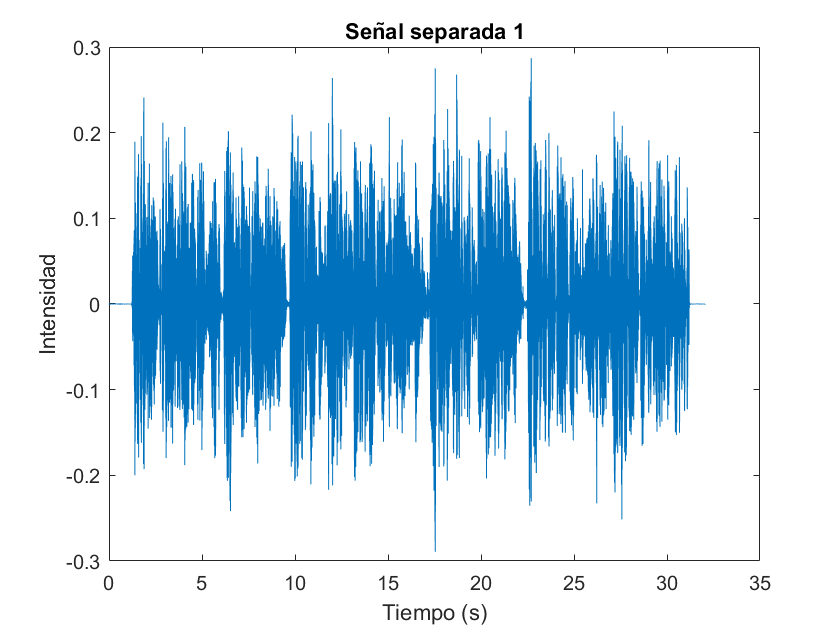

figure()
plot(tArray, separatedSignal1)
title("Señal separada 1")
xlabel("Tiempo (s)")
ylabel("Intensidad")

sound(separatedSignal1,Fs);

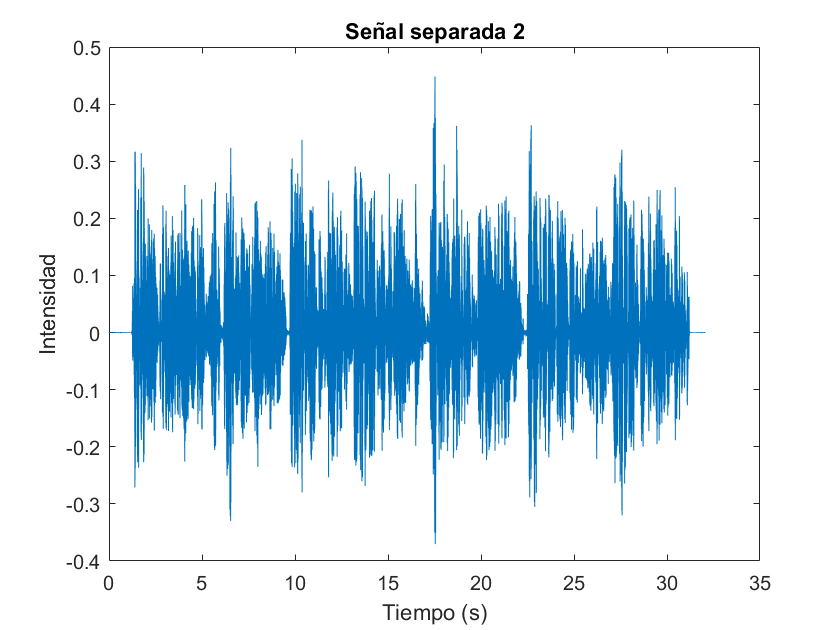



separatedSignal2 = separator.separateSignal(2, tArray, signals);
figure()
plot(tArray, separatedSignal2)
title("Señal separada 2")
xlabel("Tiempo (s)")
ylabel("Intensidad")


sound(separatedSignal2, Fs)


audiowrite("separado_2.wav", separatedSignal2, Fs);